Function

f=@(x) 400.*x.^5 - 900.*x.^4 + 675.*x.^3 - 200.*x.^2 + 25.*x + 0.2;
xx = linspace(0,0.8)

xx =          0    0.0081    0.0162    0.0242    0.0323    0.0404    0.0485    0.0566    0.0646    0.0727    0.0808    0.0889    0.0970    0.1051    0.1131    0.1212    0.1293    0.1374    0.1455    0.1535    0.1616    0.1697    0.1778    0.1859    0.1939    0.2020    0.2101    0.2182    0.2263    0.2343    0.2424    0.2505    0.2586    0.2667    0.2747    0.2828    0.2909    0.2990    0.3071    0.3152    0.3232    0.3313    0.3394    0.3475    0.3556    0.3636    0.3717    0.3798    0.3879    0.3960


yy = f(xx)

yy =     0.2000    0.3893    0.5546    0.6978    0.8209    0.9258    1.0140    1.0874    1.1474    1.1956    1.2334    1.2621    1.2829    1.2972    1.3059    1.3101    1.3108    1.3090    1.3054    1.3008    1.2960    1.2915    1.2881    1.2862    1.2863    1.2889    1.2943    1.3029    1.3148    1.3305    1.3500    1.3735    1.4010    1.4327    1.4686    1.5086    1.5527    1.6007    1.6527    1.7083    1.7675    1.8300    1.8956    1.9640    2.0349    2.1081    2.1832    2.2598    2.3377    2.4164


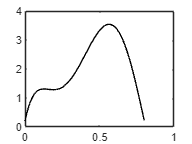

plot(xx,yy,'k-')

To integrate function from 0 to 0.8

a = 0

a = 0

b = 0.8

b = 0.8000

p =[400 -900 675 -200 25 0.2]

p =   400.0000 -900.0000  675.0000 -200.0000   25.0000    0.2000


q = polyint(p)

q =    66.6667 -180.0000  168.7500  -66.6667   12.5000    0.2000         0


Itrue = diff(polyval(q,[a,b]))

Itrue = 1.6405

Plot original function along with trapezoidal rule ns = 1

ns = 1

ns = 1

x = linspace(a,b,ns+1)

x =          0    0.8000


y = f(x)

y =     0.2000    0.2320


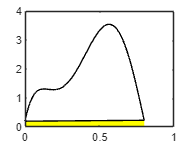


figure
area(x,y,'FaceColor','y','EdgeColor','black','LineStyle','-')
hold on
plot(xx,yy,'k-')

I_trap_1 = trap(f,a,b,1)

I_trap_1 = 0.1728

Plot original function along with trapezoidal rule ns = 2

ns = 2

ns = 2

x = linspace(a,b,ns+1)

x =          0    0.4000    0.8000


y = f(x)

y =     0.2000    2.4560    0.2320



figure 
color=['g','y']

color = 'gy'

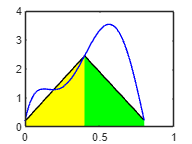

for i = 1:ns
    area(x(i:i+1),y(i:i+1),'FaceColor',color(mod(i,2)+1),'EdgeColor','black','LineStyle','-')    
    hold on
end
plot(xx,yy,'b-')

Plot original function along with trapezoidal rule ns = 3

ns = 3

ns = 3

x = linspace(a,b,ns+1)

x =          0    0.2667    0.5333    0.8000


y = f(x)

y =     0.2000    1.4327    3.4872    0.2320



figure 
color=['g','y']

color = 'gy'

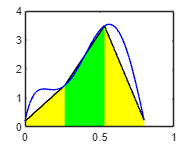

for i = 1:ns
    area(x(i:i+1),y(i:i+1),'FaceColor',color(mod(i,2)+1),'EdgeColor','black','LineStyle','-')    
    hold on
end
plot(xx,yy,'b-')

Plot original function along with trapezoidal rule ns from 1 until 10

Plot original function along with trapezoidal rule ns = 3

ns = 4

x =          0    0.2000    0.4000    0.6000    0.8000


y =     0.2000    1.2880    2.4560    3.4640    0.2320


color = 'gy'

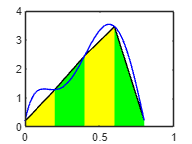

ns = 5

x =          0    0.1600    0.3200    0.4800    0.6400    0.8000


y =     0.2000    1.2969    1.7434    3.1860    3.1819    0.2320


color = 'gy'

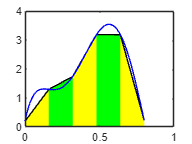

ns = 6

x =          0    0.1333    0.2667    0.4000    0.5333    0.6667    0.8000


y =     0.2000    1.3102    1.4327    2.4560    3.4872    2.8749    0.2320


color = 'gy'

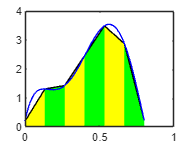

ns = 7

x =          0    0.1143    0.2286    0.3429    0.4571    0.5714    0.6857    0.8000


y =     0.2000    1.3067    1.3189    1.9245    2.9984    3.5379    2.5990    0.2320


color = 'gy'

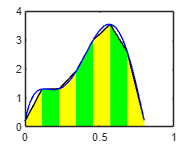

ns = 8

x =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000


y =     0.2000    1.2890    1.2880    1.6070    2.4560    3.3250    3.4640    2.3630    0.2320


color = 'gy'

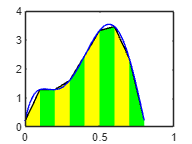

ns = 9

x =          0    0.0889    0.1778    0.2667    0.3556    0.4444    0.5333    0.6222    0.7111    0.8000


y =     0.2000    1.2621    1.2881    1.4327    2.0349    2.8842    3.4872    3.3337    2.1634    0.2320


color = 'gy'

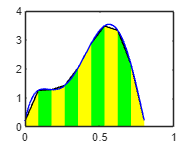

ns = 10

x =          0    0.0800    0.1600    0.2400    0.3200    0.4000    0.4800    0.5600    0.6400    0.7200    0.8000


y =     0.2000    1.2300    1.2969    1.3437    1.7434    2.4560    3.1860    3.5396    3.1819    1.9944    0.2320


color = 'gy'

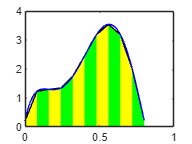

ns = 11

x =          0    0.0727    0.1455    0.2182    0.2909    0.3636    0.4364    0.5091    0.5818    0.6545    0.7273    0.8000


y =     0.2000    1.1956    1.3054    1.3029    1.5527    2.1081    2.8088    3.3786    3.5228    3.0262    1.8504    0.2320


color = 'gy'

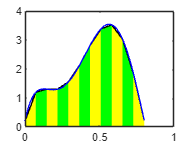

ns = 12

x =          0    0.0667    0.1333    0.2000    0.2667    0.3333    0.4000    0.4667    0.5333    0.6000    0.6667    0.7333    0.8000


y =     0.2000    1.1605    1.3102    1.2880    1.4327    1.8461    2.4560    3.0797    3.4872    3.4640    2.8749    1.7268    0.2320


color = 'gy'

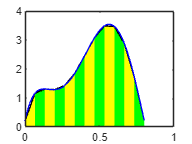

ns = 13

x =          0    0.0615    0.1231    0.1846    0.2462    0.3077    0.3692    0.4308    0.4923    0.5538    0.6154    0.6769    0.7385    0.8000


y =     0.2000    1.1258    1.3106    1.2864    1.3603    1.6568    2.1599    2.7557    3.2748    3.5343    3.3808    2.7320    1.6198    0.2320


color = 'gy'

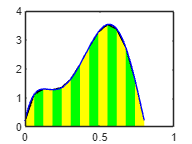

for i = 1:10
    ns = ns+1
    x = linspace(a,b,ns+1)
    y = f(x)

    figure 
    color=['g','y']
    for i = 1:ns
        area(x(i:i+1),y(i:i+1),'FaceColor',color(mod(i,2)+1),'EdgeColor','black','LineStyle','-')
        hold on
    end
    plot(xx,yy,'b-')
end